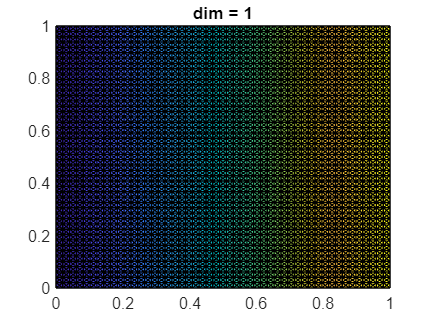

clear all;

% Create Mesh
x1      = linspace(0, 1, 50);
x2      = linspace(0, 1, 50);
[xv,yv] = meshgrid(x1,x2);
[F,V]   = mesh2tri(xv,yv,zeros(size(xv)),'x');
s.coord  = V(:,1:2);
s.connec = F;
mesh = Mesh.create(s);

% % Create Scalar Domain Function
% s.operation = @(xV) xV;
% s.mesh      = mesh;
% linear = DomainFunction(s);
% 
% s.operation = @(xV) xV.^2;
% s.mesh      = mesh;
% quadratic = DomainFunction(s);
% 
% % Scalar Function Times Scalar Function
% % Lets consider f(x) = x and g(x) = x^2. We want to compute h(x) = f(x)g(x)
% 
% cubic = linear.*quadratic 
% x = linspace(-1,1,50);
% plot(x,cubic.evaluate(x))

% f(x,y) = x
linear = LagrangianFunction.create(mesh,1,'P1');
dofs = linear.getDofCoord;
linear.setFValues(dofs(:,1)); % as Lagrangian Function
linear.plot();


s.operation = @(xV) linear.evaluate(xV)

s = struct with fields:
        coord: [4901×2 double]
       connec: [9604×3 double]
    operation: @(xV)linear.evaluate(xV)


s.mesh      = mesh;
linearDF = DomainFunction(s); % as Domain Function
linearDF.plot();

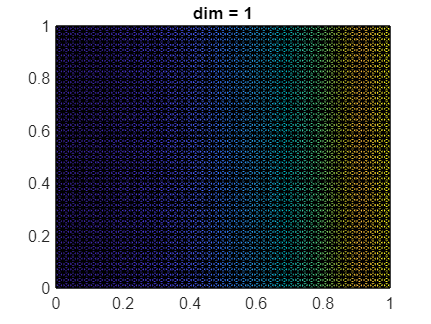


% g(x,y) = x^2
quadratic = LagrangianFunction.create(mesh,1,'P1');
dofs = quadratic.getDofCoord;
quadratic.setFValues(dofs(:,1).^2);
quadratic.plot();


s.operation = @(xV) quadratic.evaluate(xV)

s = struct with fields:
        coord: [4901×2 double]
       connec: [9604×3 double]
    operation: @(xV)quadratic.evaluate(xV)
         mesh: [1×1 SurfaceMesh]


s.mesh      = mesh;
quadraticDF = DomainFunction(s); % as Domain Function
quadraticDF.plot();


% Product of Two Scalar Lagrangian Functions
% h(x,y) = f(x,y)g(x,y)
cubic = linear.*quadratic       % Scalar Domain Function

cubic =   DomainFunction with properties:

    operation: @(xV)aOp(xV).*bOp(xV)
         mesh: [1×1 SurfaceMesh]
        ndimf: 1


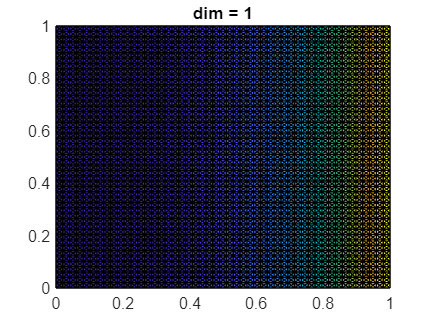

cubic.plot()   


% Product of Two Scalar Lagrangian Functions
% h(x,y) = f(x,y)g(x,y)
cubicDF = linearDF.*quadraticDF % Scalar Domain Function

cubicDF =   DomainFunction with properties:

    operation: @(xV)aOp(xV).*bOp(xV)
         mesh: [1×1 SurfaceMesh]
        ndimf: 1


cubicDF.plot() 

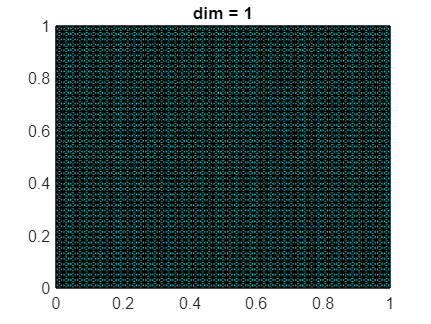


% Scalar Product of Two Vector Domain Functions
dot = DP(Grad(linear), Grad(linear));
dot.plot();                     % Scalar Domain Function

 
% Scalar Product of a Scalar timea a Vector Domain Function
product = linearDF.*Grad(linear);

Unrecognized method, property, or field 'computeGrad' for class 'DomainFunction'.

Error in Grad (line 2)
 gradU = u.computeGrad();

% product.plot();               % Should be a Vector Domain Function. Does not work.   

